## PLS example

This example demonstrates how to perform PLS regression and how to choose the number of components in a PLS model.

We use the same data (Heat of reaction for cement) as the PCA example

### Load the data

% Load the hald data set
load hald

% Separate the predictors (ingredients) and response (heat)
X = ingredients; % First 4 columns (predictors)
Y = heat;        % Last column (response)

Use [`plsregress`](https://au.mathworks.com/help/stats/plsregress.html) to perform PLS regression with the same number of components as predictors, then plot the percentage variance explained in the response as a function of the number of components.

% Here, we use the number of predictors as number of components
nComponents = 4;

% Create the PLS model
[XL, YL, XS, YS, beta, PCTVAR, MSE, stats] = plsregress(X, Y, nComponents);

% Display the regression coefficients
disp('PLS Regression Coefficients:');

PLS Regression Coefficients:


disp(beta);

   62.4054
    1.5511
    0.5102
    0.1019
   -0.1441



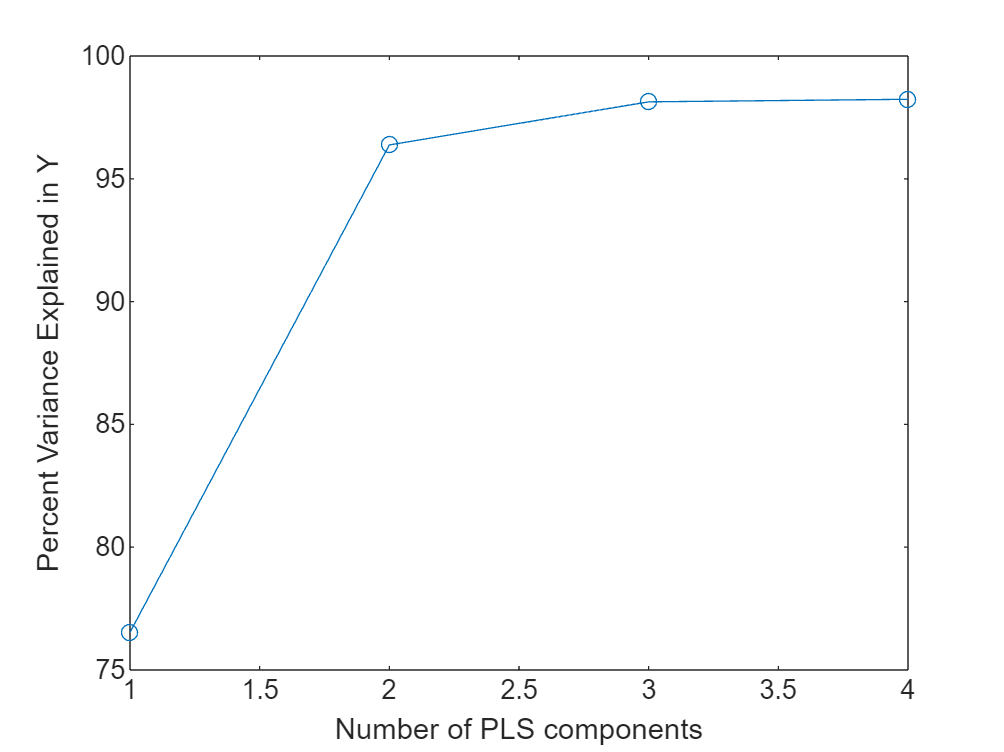


plot(1:nComponents,cumsum(100*PCTVAR(2,:)),'-o')
xlabel('Number of PLS components')
ylabel('Percent Variance Explained in Y')

Choosing the number of components in a PLS model is a critical step. The plot gives a rough indication, showing nearly 96% of the variance in Y explained by the first two components.

The following computes the two model.

% 2 component model
nComponents = 2;

% Create the PLS model
[XL, YL, XS, YS, beta, PCTVAR, MSE, stats] = plsregress(X, Y, nComponents);

% Predict the response for the training data
Y_pred = [ones(size(X,1),1) X] * beta;

% Display the predicted response
disp('Predicted Response (Heat) for Training Data:');

Predicted Response (Heat) for Training Data:


disp(Y_pred);

   80.7965
   74.3832
  106.6746
   88.7767
   99.0107
  104.9566
  104.8211
   73.3445
   92.1342
  111.5338
   79.2297
  112.1361
  112.7023



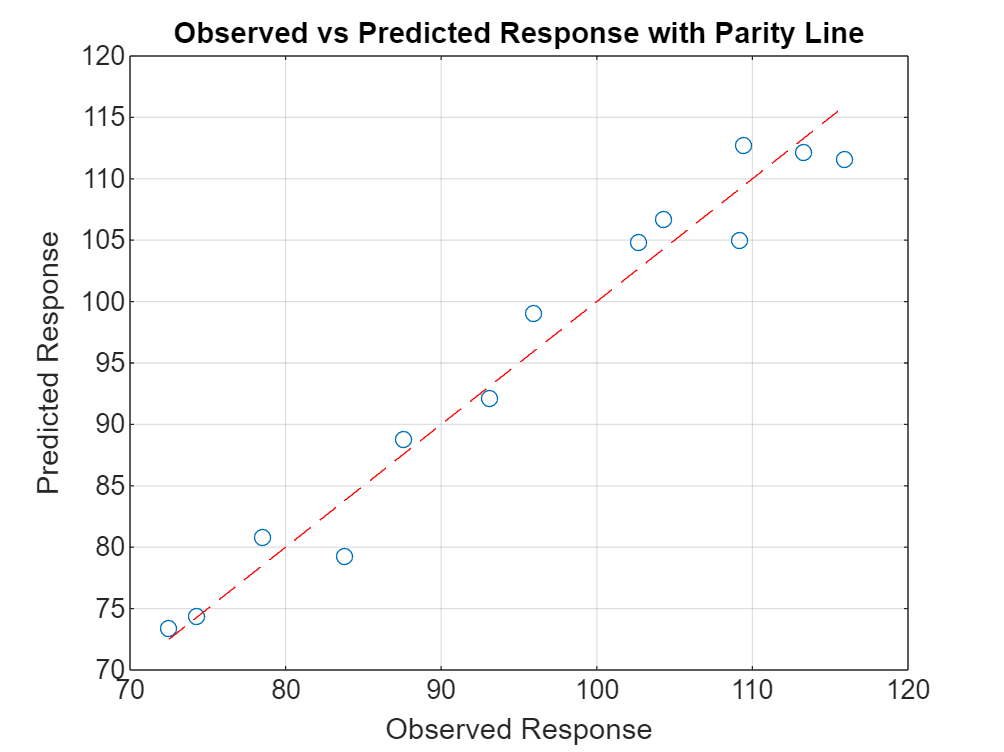


% Plot the observed vs predicted response
figure;
plot(Y, Y_pred, 'o'); % Plot the observed vs predicted response
hold on;
plot([min(Y), max(Y)], [min(Y), max(Y)], 'r--'); % Draw the parity line
xlabel('Observed Response');
ylabel('Predicted Response');
title('Observed vs Predicted Response with Parity Line');
grid on;
hold off;

The scatter shows a reasonable correlation between fitted and observed responses, and this is confirmed by the $R^2$statistic.

TSS = sum((Y-mean(Y)).^2);
RSS = sum((Y-Y_pred).^2);
Rsquared = 1 - RSS/TSS

Rsquared = 0.9638